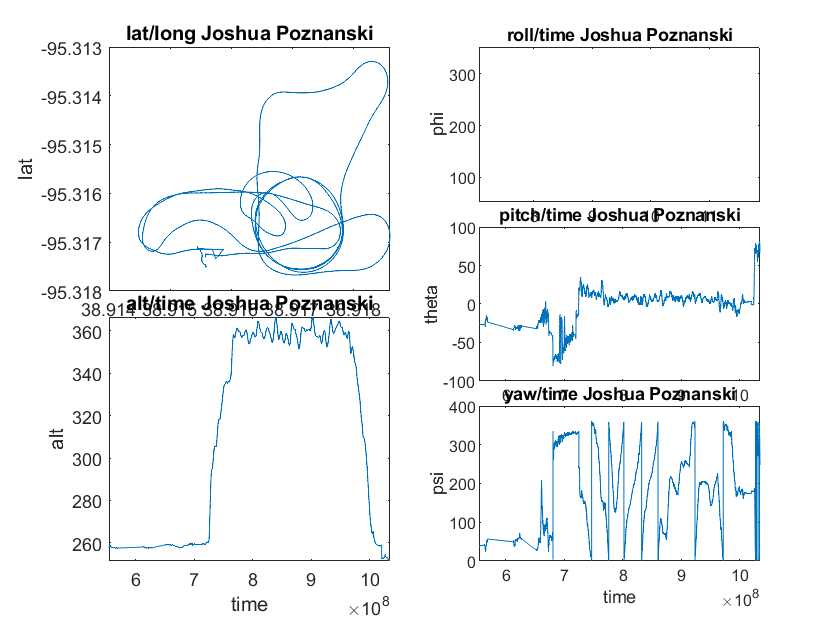

latG = GPS(:,9);
longG = GPS(:,8);
altG = GPS(:,10);
timeG = GPS(:,2);

altB = BARO(:,3);
timeB = BARO(:,2);

lat = POS(:,3);
long = POS(:,4);
alt = POS(:,5);
timePOS = POS(:,2);

roll = ATT(:,4);
pitch = ATT(:,6);
yaw = ATT(:,8);
timeATT = ATT(:,2);
% 
% actualATTTime = timeATT(:) - timeATT(1)
% actualATTTime = actualATTTime * 0.000001
% 
% time8 = 8*(10^5)%+timeATT(1)
% time82 = 8.2*(10^5)%+timeATT(1)
% 
% roll()
% pitch(time8)
% yaw(time8)
% roll(time82)
% pitch(time82)
% yaw(time82)


figure

subplot(6,2,[1,3,5]);
plot(lat,long);
title("lat/long" + " Joshua Poznanski")
xlabel("long");
ylabel("lat");

subplot(6,2,[7,9,11]);
plot(timePOS,alt);
title("alt/time" + " Joshua Poznanski")
xlabel("time");
ylabel("alt");

% hold on;
% plot(timeG,altG-altG(1));


subplot(6,2,[2,4]);
plot(timeATT,roll);
title("roll/time" + " Joshua Poznanski")
xlabel("time");
ylabel("phi");

subplot(6,2,[6,8]);
plot(timeATT,pitch);
title("pitch/time" + " Joshua Poznanski")
xlabel("time");
ylabel("theta");

subplot(6,2,[10,12]);
plot(timeATT,yaw);
title("yaw/time" + " Joshua Poznanski")
xlabel("time");
ylabel("psi");